## Problem 1

We first introduced the notion of impulse response in Chapter 1, and here in Chapter 5 we discussed the importance of knowing the impulse response of FIR filter networks. With that said, if the y(n) output of a discrete system is equal to the system’s x(n) input sequence: 

(a) Draw the unit impulse response of such a system.

 (b) Draw the block diagram (structure) of that system.

 (c) What is the frequency magnitude response of such a system? Prove your answer

**Answer:**

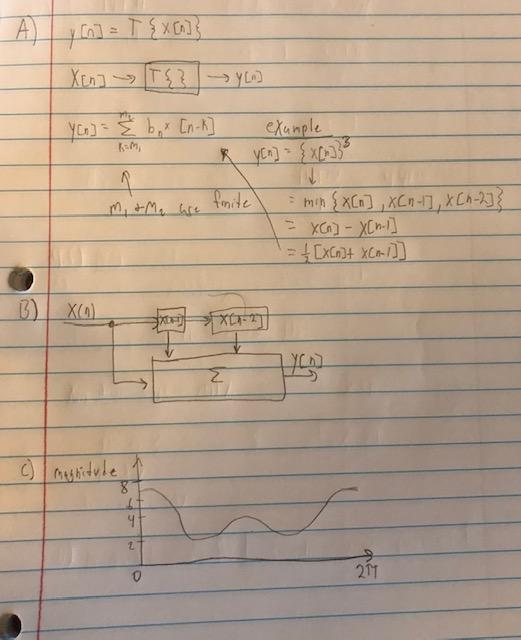

## Problem 2

Consider a simple analog signal defined by x(t) = cos(2π800t) shown in Figure P5-2. The FIR lowpass filter has a passband extending from −400 Hz to +400 Hz, a passband gain of unity, a transition region width of 20 Hz, and a stopband attenuation of 60 dB. 

(a) Draw the spectral magnitude of x(n) showing all spectral components in the range of −2fs to +2fs . 

(b) Draw the spectral magnitude of y(n) showing all spectral components in the range of −2fs to +2fs . 

(c) What is the time-domain peak amplitude of the sinusoidal y(n) output?

**Answer:** 

fs = 1000; %sampling speed
t=0:1/1:fs

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



x= cos(2*pi*800*t);
fpass= 400;

lowpass(x,fpass,fs);


A)

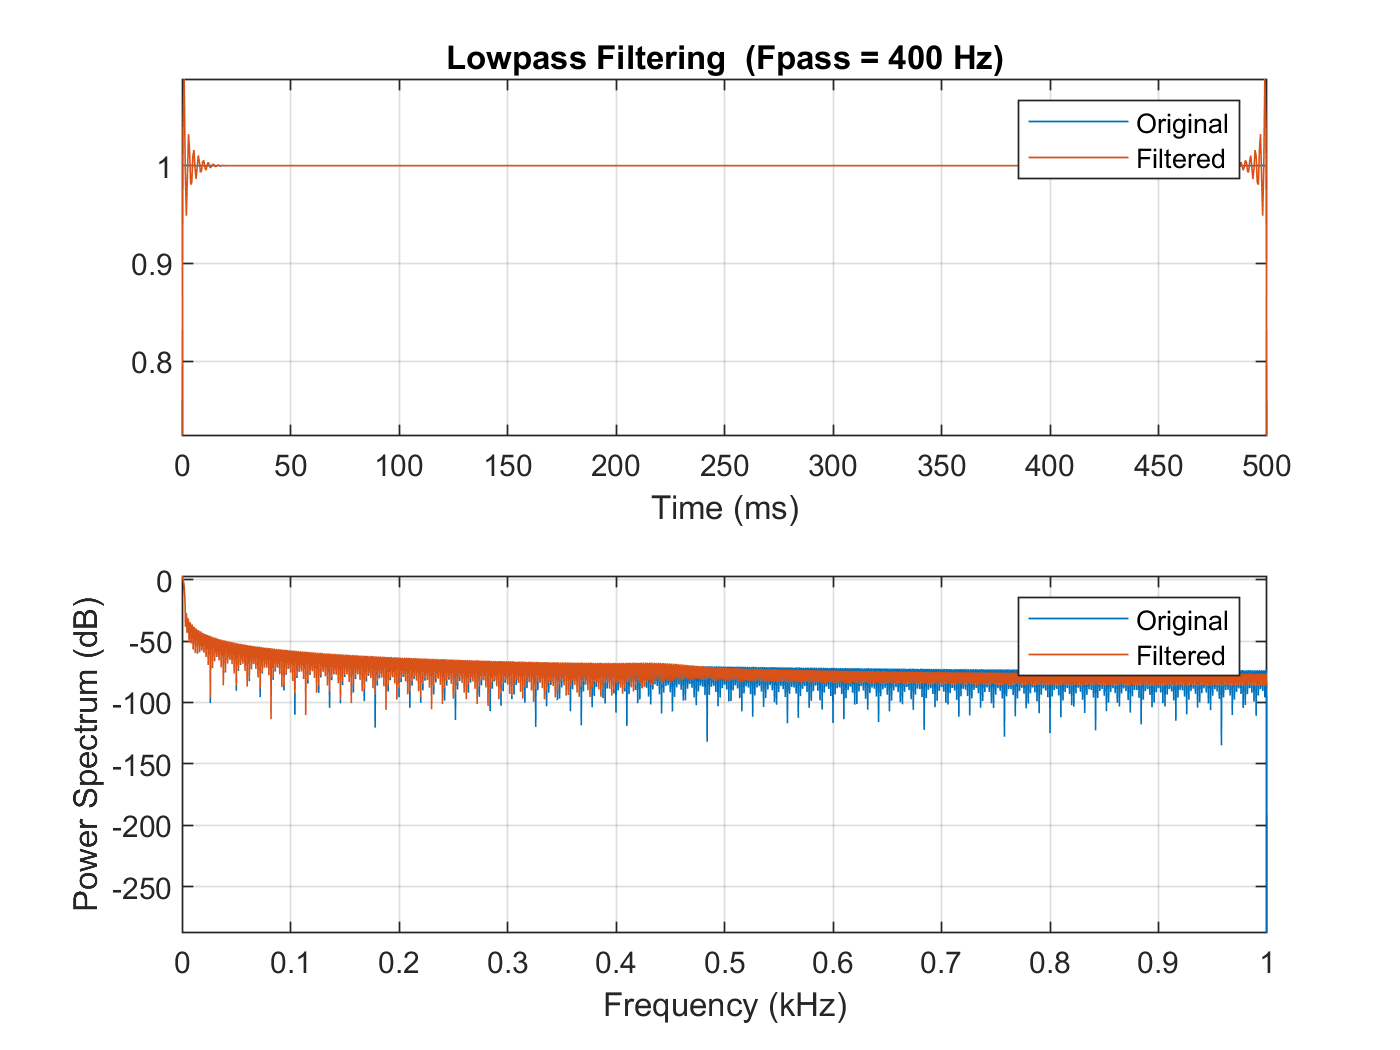

lowpass(x,fpass,2000);

B)

lowpass(x,fpass,2000);

C) 1.082 is the peak domain ampitude

## Problem 3

Assume we want to filter the audio signal from a digital video disc (DVD) player as shown in Figure P5-3. The filtered audio signal drives, by way of a digital-to-analog (D/A) converter, a speaker. For the audio signal to have acceptable time synchronization with the video signal, video engineers have determined that the time delay of the filter must be no greater than 6×10 −3 seconds. If the fs sample rate of the audio is 48 kHz, what is the maximum number of taps in the FIR filter that will satisfy the time delay restriction? (Assume a linear-phase FIR filter, and zero time delay through the D/A converter.) 

**Answer:**


$$\begin{array}{l}
\frac{1}{2}\left(x-1\right)=\left(6*{10}^{-3} \right)*48000\\
x-1=576\\
x=577
\end{array}$$


The maximum number of taps is 577

## Problem 4

There are times when we want to build a lowpass filter and a highpass filter that are complementary. By “complementary” we mean that a highpass filter’s passband covers the frequency range defined by a lowpass filter’s stopband range. This idea is illustrated in Figure P5- 4(a). An example of such filters is an audio system, shown in Figure P5-4(b), where the lowfrequency spectral components of an x(n) audio signal drive, by way of a digital-to-analog (D/A) converter, a low-frequency speaker (woofer). Likewise, the high-frequency spectral components of x(n) drive a high-frequency speaker (tweeter). Audio enthusiasts call Figure P5-4(b) a “crossover” network. Assuming that the lowpass filter is implemented with a 15-tap FIR filter whose hLow(k) coefficients are those in Figure P5-4(c), the complementary highpass filter will have the coefficients shown in Figure P5-4(d). Highpass coefficients hHigh (k) are defined by

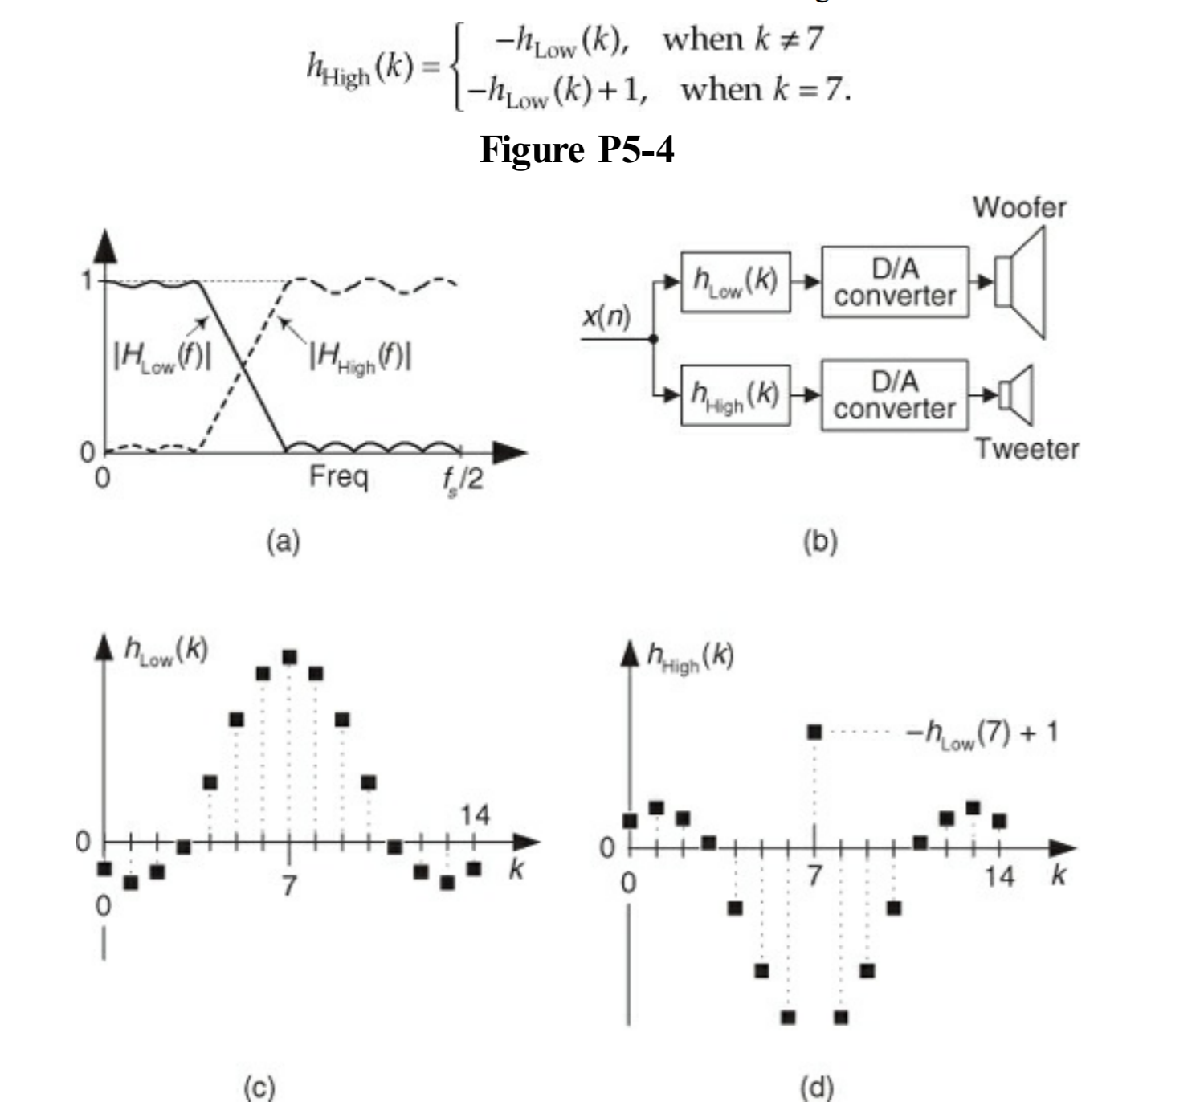

Here is the problem: Draw a block diagram of a system that performs the process in P5-4(b) where only the hLow(k) lowpass FIR filter need be implemented. 

**Answer:** 

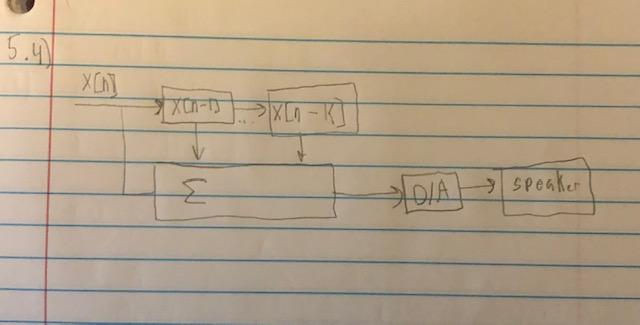

## Problem 5

Think about a discrete System A, shown in Figure P5-5, that has an undesirable amplitude (gain) loss by a factor 0.5 (−6 dB), whose output requires lowpass linear-phase filtering. What can we do in the design of the lowpass FIR filter so the filter has an amplitude gain of 2 to compensate for System A’s amplitude loss?

**Answer:** 

To compensate for system A's amplitude loss a lowpass FIR filtercan be designed so the filter has an amplitude gain of 2. 


$$y\left\lbrack n\right\rbrack =\sum_{K=N}^{M-1} h\left(k\right)x\left(n-k\right)$$



$$\begin{array}{l}
d\left\lbrack n\right\rbrack =\delta \left\lbrack n-1\right\rbrack \\
\left|y\left\lbrack n\right\rbrack \right|=|h\left\lbrack n\right\rbrack *x\left\lbrack n\right\rbrack |
\end{array}$$


from this you get


$$|\sum_{k=-\infty }^{\infty } h\left\lbrack k\right\rbrack *x\left\lbrack n-k\right\rbrack |\le \sum_{k=-\infty }^{\infty } |h\left\lbrack k\right\rbrack *x\left\lbrack n-k\right\rbrack |\le \sum_{k=-\infty }^{\infty } |h\left\lbrack n\right\rbrack |$$


The summation of the last term is finite if h[n] is absolutely summable if it is not absolutely summable consider the signal 

x[n] = sin(h[n])

x[n] is bounded since the only values it takes is -1,0,1

## Problem 6

Let’s assume we have an x(n) time sequence, whose fs sample rate is 20 kHz, and its |X(f)| spectral magnitude is that shown in Figure P5-6(a). We are required to design a linear-phase lowpass FIR filter that will attenuate the undesired high-frequency noise indicated in Figure P5- 6(a). So we design a lowpass FIR filter whose frequency magnitude response is the |H(f)| shown in Figure P5-6(b) and assume our filter design exercise is complete. Sometime later, unfortunately, we learn that the original x(n) sequence’s sample rate was not 20 kHz, but is in fact 40 kHz

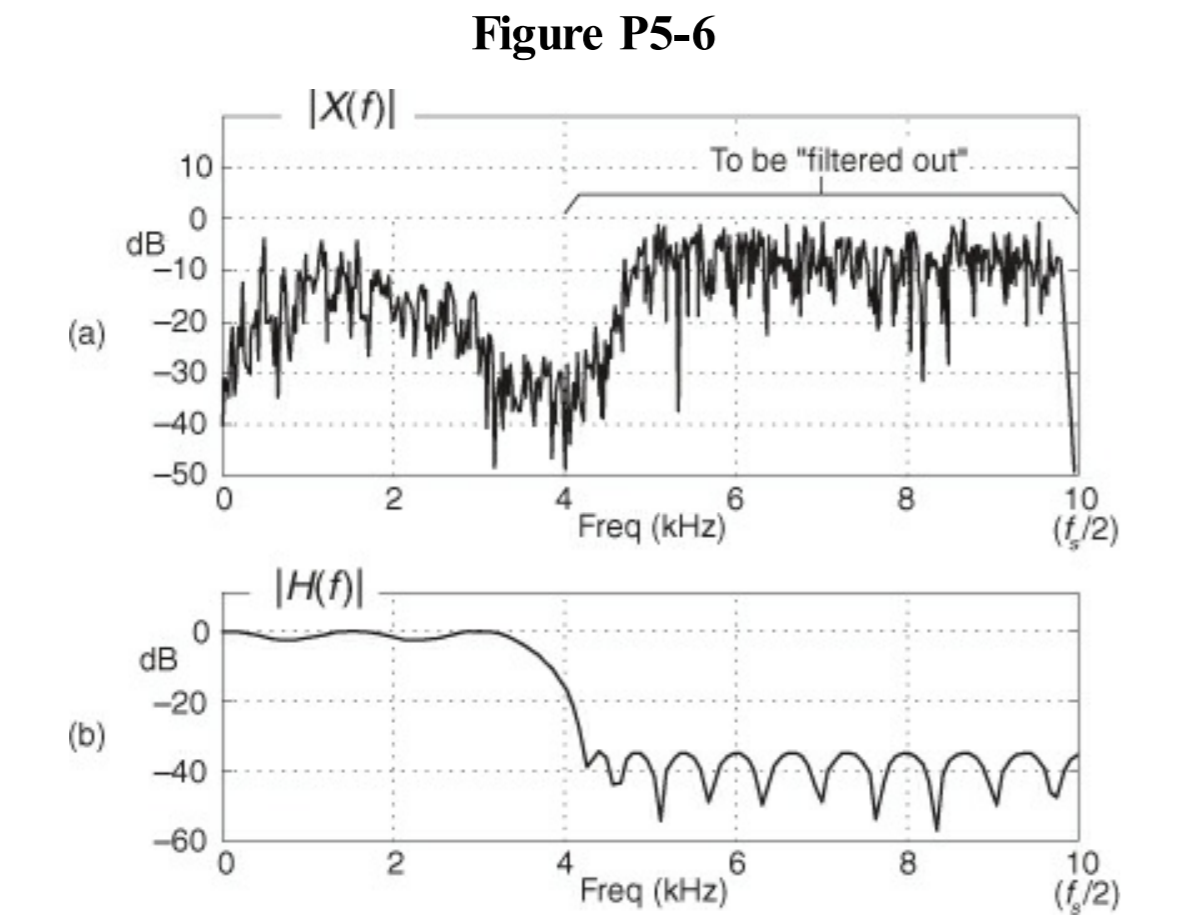

Here is the problem: What must we do to our lowpass filter’s h(k) coefficients, originally designed based on a 20 kHz sample rate, so that they will still attenuate x(n)’s undesired high-frequency noise when the fs sample rate is actually 40 kHz? 

**Answer:** 

For the lowpass filter to work the h(k) coefficient must be divided by 2 because 40kHz is double 20kHz.

## Problem 7

Here is an interesting little problem. Think about applying the sinusoidal input sequence shown in Figure P5-7(a) to an 8-point moving average FIR filter. The filter’s output sequence is that depicted in Figure P5-7(b). 

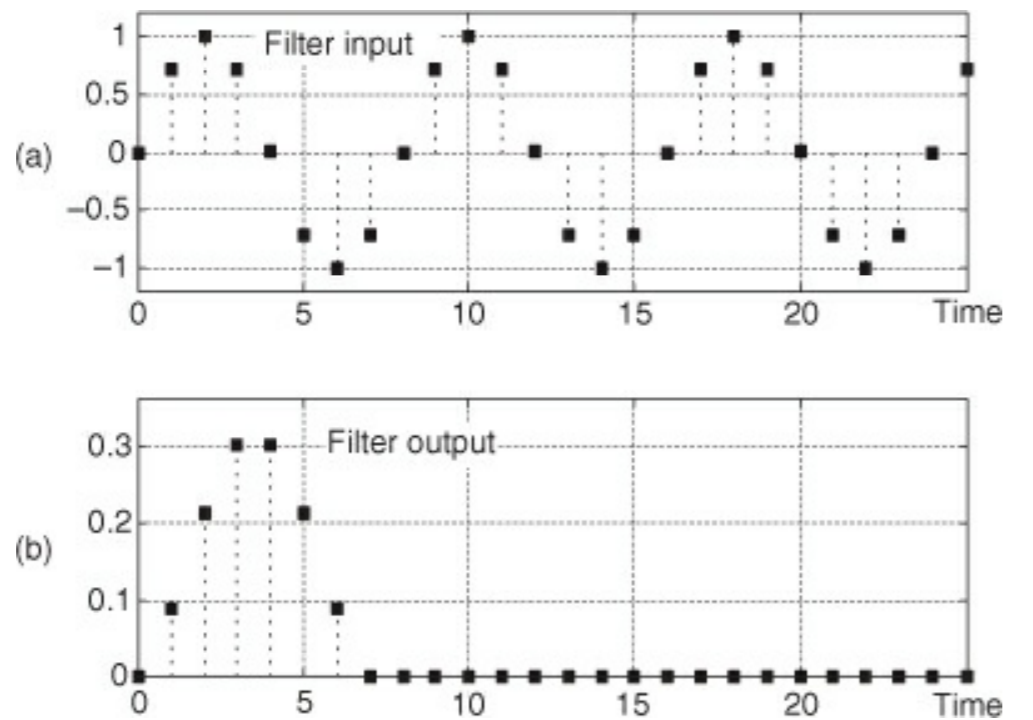

(a) What characteristic of the filter’s frequency response causes the filter’s output sequence to go to all zeros as shown in Figure P5-7(b)?

 (b) In Figure P5-7(b), what do we call those initial nonzero-valued filter output samples? 

**Answer:** 

A) The magnitude resonse reached zero so the gain contribution of the moving average filter at this frequncy is 0

B) The nonzero-valued filter output sample are called  the transient response of the filter

## Problem 8

Are abrupt (sudden) changes in the amplitude of a continuous, or discrete, signal associated with low or high frequencies? 

**Answer:**

Abrupt changes in the amplitude are associated with a high frequency

## Problem 9

Consider an FIR filter whose impulse response is shown in Figure P5-9(a). Given the x(n) filter input sequence shown in Figure P5-9(b):

 (a) What is the length, measured in samples, of the nonzero-valued samples of the filter’s output sequence? 

(b) What is the maximum sample value of the filter’s output sequence? 

**Answers:** 

A) The length of the nonzero-valued samples of the filter's output sequence is 5

B) The maximum sample value of the filter's output sequence is 2